clear;

% Global
load("HW1_data.mat");
xData = HW1_data.Xdata;
yData = HW1_data.Ydata;

xCoarse = -1 + (0:10)*6/10;

% Polynomial fitting
polyCoeff = PolynomialFit(xData, yData, 15);
xx = linspace(min(xData), max(xData), 256);
yy = polyval(polyCoeff, xx);

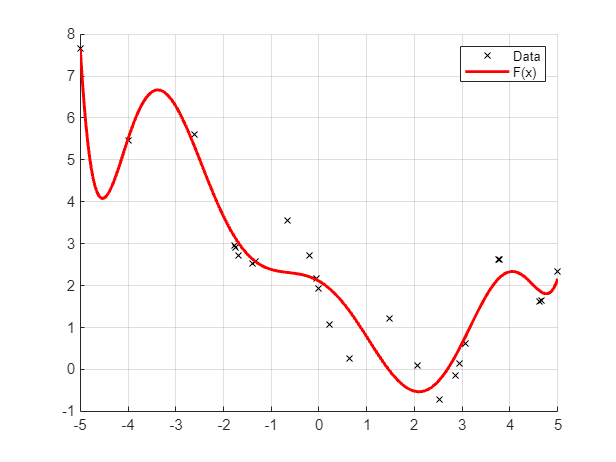

% Plotting
f = figure();

grid on;
legend('Location', 'northeast');
xticks(-5:1:5);

hold on;
plot(xData, yData, 'kx', ...
    'DisplayName', "Data");
plot(xx, yy, 'r-', 'LineWidth', 2, ...
    'DisplayName', "F(x)");
hold off;

exportgraphics(f, [pwd '/figures/HW1_q2.png'])